Pull values from constants file

clc
clear
close all

c = get_constants()

c = struct with fields:
          LENGTH: 1200
       TRAIN_DIM: [52 176 164 176 164 176 52]
    TRAIN_LOAD_1: [67.5000 67.5000 67.5000 67.5000 91 91]
    TRAIN_LOAD_2: [1 1 1 1 1.3500 1.3500]


% assuming, for the sake of analysis, heavy part
% of train is in the rear.
x = 120;
load_factor = -1;
N = 200;

Calculate loads and distances

if (load_factor == -1)
    train_load = c.TRAIN_LOAD_1;
else
    train_load = load_factor * c.TRAIN_LOAD_2;
end

Calculate reaction forces

function [reaction_a,reaction_b] = reaction_forces(train_distance,train_load)
    % given the start of the train is x m from the left,
    % return the reaction forces at each support.
    
    % this only concerns vertical forces, since no
    % horizontal load is applied.

    % constraints: 0 <= x <= length - length of train
    c = get_constants();
    
    
    train_moments_a = train_distance .* train_load;
    reaction_b = sum(train_moments_a) / c.LENGTH;
    reaction_a = sum(train_load) - reaction_b;
end

Create SFD and BMD

function [SFD,BMD] = Graph(x, train_distance, train_load, do_plot)
    c = get_constants();

    cumulative_distances = cumsum(train_distance(1:end-1)) + x;
    [reaction_a, reaction_b] = reaction_forces(cumulative_distances,train_load);

    % SFD
    SFD_forces = [reaction_a -train_load reaction_b];
    SFD_net_forces = cumsum(SFD_forces);
    force_distances = [0 cumulative_distances c.LENGTH];
    
    if do_plot == 1
        figure;
        stairs([0,force_distances],[0,SFD_net_forces]);
        title('Shear Force Diagram')
        xlabel('Distance from start (mm)')
        ylabel('Shear force (N)')
        hold on
        yline(0)
        hold off
    end

    SFD = [[0,force_distances];[0,SFD_net_forces]];

    % BMD
    
    distance_intervals = abs(force_distances(2:end) - force_distances(1:end-1));
    BMD_moments = SFD_net_forces(1:end-1) .* distance_intervals;
    BMD_net_moments = cumsum(BMD_moments);

    if do_plot == 1
        figure;
        plot(force_distances,[0,BMD_net_moments]);
        title('Bending Moment Diagram')
        xlabel('Distance from start (mm)')
        ylabel('Bending moment (Nmm)')
        hold on
        yline(0)
        hold off
    end

    BMD = [force_distances;[0,BMD_net_moments]];
end

[SFD, BMD] = Graph(x, c.TRAIN_DIM, train_load,0);

Create 3D variants in respect to x

Xs = linspace(0,240,N)

Xs =          0    1.2060    2.4121    3.6181    4.8241    6.0302    7.2362    8.4422    9.6482   10.8543   12.0603   13.2663   14.4724   15.6784   16.8844   18.0905   19.2965   20.5025   21.7085   22.9146   24.1206   25.3266   26.5327   27.7387   28.9447   30.1508   31.3568   32.5628   33.7688   34.9749   36.1809   37.3869   38.5930   39.7990   41.0050   42.2111   43.4171   44.6231   45.8291   47.0352   48.2412   49.4472   50.6533   51.8593   53.0653   54.2714   55.4774   56.6834   57.8894   59.0955


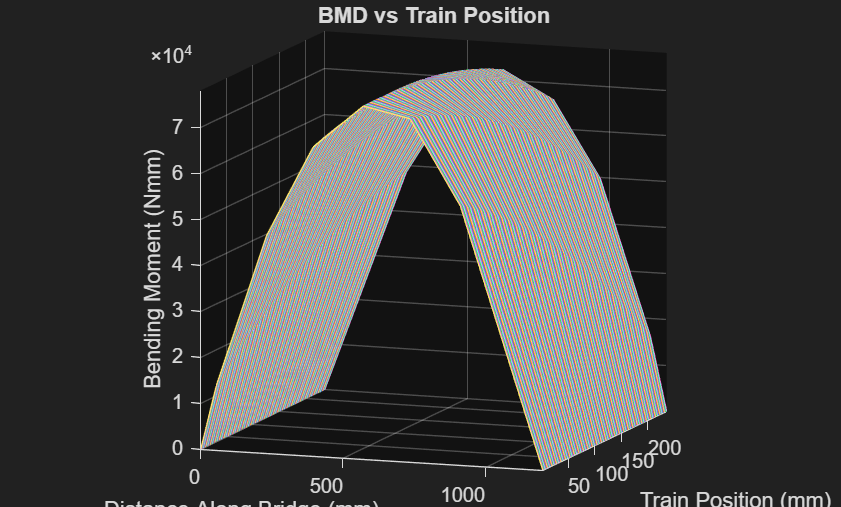


set(0, 'DefaultFigureVisible', 'off');
[SFDs, BMDs] = arrayfun(@(x) Graph(x,c.TRAIN_DIM, train_load, 0), Xs, UniformOutput=false);
set(0, 'DefaultFigureVisible', 'on');

fig = figure(Name='BMD vs Train Position');
ax = axes(fig);
cla reset; hold on;
for i=1:length(Xs)
    x_vec = BMDs{i}(1, :);
    y_vec = BMDs{i}(2, :);
    z_vec = repmat(Xs(i), size(x_vec));

    plot3(x_vec,z_vec,y_vec)
end
hold off

pan off; datacursormode off; rotate3d on;
axis padded; axis vis3d; grid on;
ax.OuterPosition = [0.05 0.05 0.9 0.88];
view(ax, 20, 10);

title('BMD vs Train Position')
xlabel('Distance Along Bridge (mm)')
ylabel('Train Position (mm)')
zlabel('Bending Moment (Nmm)')


xlim(ax,[0 1200]);